# Example: COVID-2019 data (22-Jan-2020-15-Mar-2020)

I am taking some data from Hubei province from John Hopkins university [1]

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

The fitting is here more challenging because the term "Infected patient" used in the database does not precise whether they have been quarantined or not. 

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
load('HubeiData.mat','time','Deaths','Infected','Recovered')

Recovered(Infected==0)=[];
Deaths(Infected==0)=[];
time(Infected==0)= [];
Infected(Infected==0)=[];



dt = 0.1; % time step
time1 = datetime(time(1)):dt:datetime(2020,04,01,0,0,0);
N = numel(time1);
t = [0:N-1].*dt;
Npop= 14e6; % population

## Fitting of the generalized SEIR model to the real data

guess = [0.06,1.2,1/5,1/21,0.01,0.05,0.03,0.02]; % my guess for the fit
E0 = 0; % Initial number of exposed cases (we do not know it, so it is set at zero)
I0 = Infected(1); % Initial number of infectious cases (we do not know it, so it is the number of quarantined)
Q0 = Infected(1);
R0 = Recovered(1);
D0 = Deaths(1);

[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
    fit_SEIQRDP(Infected-Recovered-Deaths,Recovered,Deaths,Npop,E0,I0,time,guess);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          9     8.58067e+11                      1.12e+14
     1         18     9.65588e+10       0.049557       1.02e+13      
     2         27     2.07915e+10      0.0710339       1.18e+11      
     3         36     2.07915e+10        0.10386       1.18e+11      
     4         45     1.54913e+10      0.0259651       4.42e+11      
     5         54     1.35743e+10      0.0519302       7.93e+10      
     6         63     1.04757e+10        0.10386       2.07e+11      
     7         72     7.05565e+09       0.207721       1.39e+11      
     8         81     7.05565e+09       0.222138       1.39e+11      
     9         90     4.34245e+09      0.0519302       2.95e+10      
    10         99     2.73727e+09        0.10386       4.91e+10      
    11        108     2.73727e+09      0.0979001       4.91e+10      
    12        117     2.22748e+0

## Simulate the epidemy outbreak based on the fitted parameters


N = numel(time1);
t = [0:N-1].*dt;
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);

## Comparison of the fited and real data

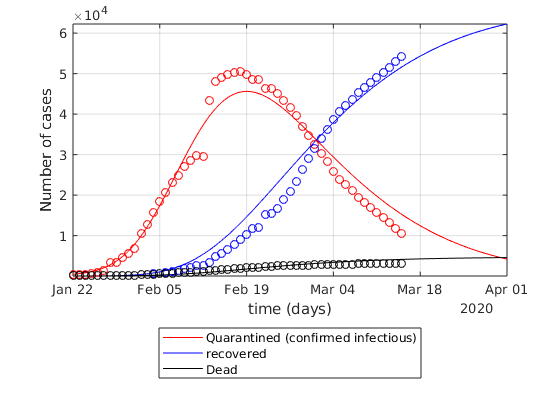

figure
semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
hold on
semilogy(time,Infected-Recovered-Deaths,'ro',time,Recovered,'bo',time,Deaths,'ko');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
% leg = {'susceptible','exposed','infectious','quarantined','recovered','Dead','insusceptible'};
leg = {'Quarantined (confirmed infectious)','recovered','Dead'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
% ylim([1,8e4])
set(gca,'yscale','lin')